clear all
clc

# Inverted Pendulum System

(**M**)     mass of the cart                                          0.5 kg

(**m**)     mass of the pendulum                                0.2 kg

(**b**)      coefficient of friction for cart                        0.1 N/m/sec

(**l**)       length to pendulum center of mass             0.3 m

(**L**)      length of pendulum                                     0.3*2 m

(**I**)       mass moment of inertia of the pendulum   0.006 kg.m^2

(**g**)      Gravity                                                        9.81 m/s^2

(**F**)      force applied to the cart                              ??  N (Unkown)

(**x**)      cart position coordinate                               0 m (Target)

(**theta**)   pendulum angle from vertical                   0 rad (Target)

M = 0.5;
m = 0.2;
b = 0.1;
l = 0.3;
L = l*2;
I = 0.006;
g = 9.81;

## **State-Space**

#### 
$$\left\lbrack \begin{array}{c}
\dot{x} \\
\ddot{x} \\
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & \frac{-\left(I+{m\;l}^2 \right)b}{I\left(M+m\right)+{M\;m\;l}^2 } & \frac{m^2 \;g\;l^2 }{I\left(M+m\right)+{M\;m\;l}^2 } & 0\\
0 & 0 & 0 & 1\\
0 & \frac{-m\;l\;b}{I\left(M+m\right)+{M\;m\;l}^2 } & \frac{m\;g\;l\left(M+m\right)}{I\left(M+m\right)+{M\;m\;l}^2 } & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x} \\
\theta \\
\dot{\theta} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{I+{m\;l}^2 }{I\left(M+m\right)+{M\;m\;l}^2 }\\
\frac{m\;l}{I\left(M+m\right)+{M\;m\;l}^2 }\\
0
\end{array}\right\rbrack F$$


#### 
$$y=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x} \\
\theta \\
\dot{\theta} 
\end{array}\right\rbrack$$


p = I*(M+m)+M*m*l^2; %denominator for the A and B matrices

A = [0      1              0           0;
     0 -(I+m*l^2)*b/p  (m^2*g*l^2)/p   0;
     0      0              0           1;
     0 -(m*l*b)/p       m*g*l*(M+m)/p  0];

B = [     0;
     (I+m*l^2)/p;
          0;
        m*l/p];

C = eye(size(A));


D = [];

states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x' 'x_dot' 'theta' 'theta_dot'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

sys_ss =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot              0    -0.1818      2.675          0
   theta              0          0          0          1
   theta_dot          0    -0.4545      31.21          0
 
  B = 
                  u
   x              0
   x_dot      1.818
   theta          0
   theta_dot  4.545
 
  C = 
                      x      x_dot      theta  theta_dot
   x                  1          0          0          0
   x_dot              0          1          0          0
   theta              0          0          1          0
   theta_dot          0          0          0          1
 
  D = 
              u
   x          0
   x_dot      0
   theta      0
   theta_dot  0
 
Continuous-time state-space model.


## **Transfer Function**

sys_tf = tf(sys_ss);

sys_tf

sys_tf =
 
  From input "u" to output...
          1.818 s^2 + 1.615e-15 s - 44.59
   x:  --------------------------------------
       s^4 + 0.1818 s^3 - 31.21 s^2 - 4.459 s
 
                   1.818 s^2 - 44.59
   x_dot:  ----------------------------------
           s^3 + 0.1818 s^2 - 31.21 s - 4.459
 
                  4.545 s - 8.153e-16
   theta:  ----------------------------------
           s^3 + 0.1818 s^2 - 31.21 s - 4.459
 
               4.545 s^2 - 8.153e-16 s - 6.5e-15
   theta_dot:  ----------------------------------
               s^3 + 0.1818 s^2 - 31.21 s - 4.459
 
Continuous-time transfer function.


P_cart = sys_tf(1)

P_cart =
 
  From input "u" to output "x":
     1.818 s^2 + 1.615e-15 s - 44.59
  --------------------------------------
  s^4 + 0.1818 s^3 - 31.21 s^2 - 4.459 s
 
Continuous-time transfer function.
Model Properties


P_pend = sys_tf(3)

P_pend =
 
  From input "u" to output "theta":
         4.545 s - 8.153e-16
  ----------------------------------
  s^3 + 0.1818 s^2 - 31.21 s - 4.459
 
Continuous-time transfer function.
Model Properties


## **System Analysis **

**1. Open-Loop Impulse Response **

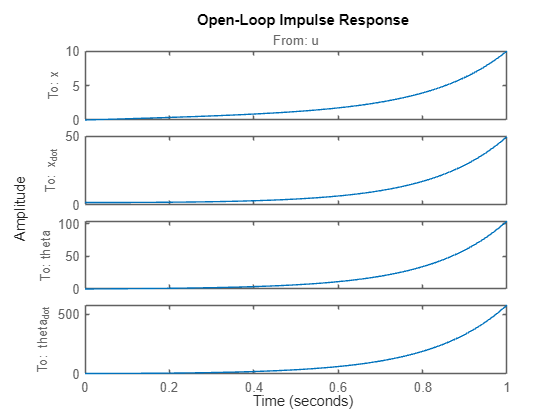

t=0:0.01:1;
impulse(sys_ss,t);
title('Open-Loop Impulse Response')

[sys_zeros,sys_poles] = zpkdata(P_pend,'v')

sys_zeros = 1.7936e-16

sys_poles =     5.5680
   -5.6069
   -0.1428


[sys_zeros,sys_poles] = zpkdata(P_cart,'v')

sys_zeros =    -4.9523
    4.9523


sys_poles =          0
    5.5680
   -5.6069
   -0.1428


sys_pole = pole(sys_ss)

sys_pole =          0
   -0.1428
   -5.6069
    5.5680


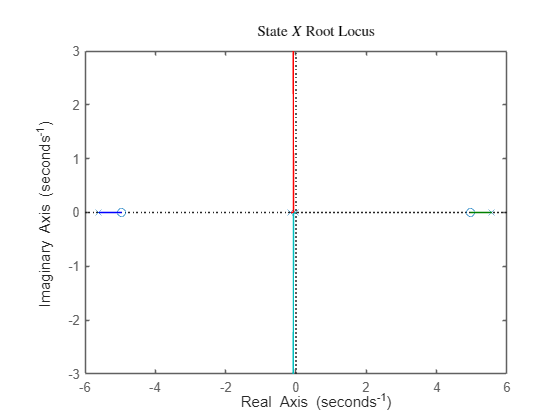

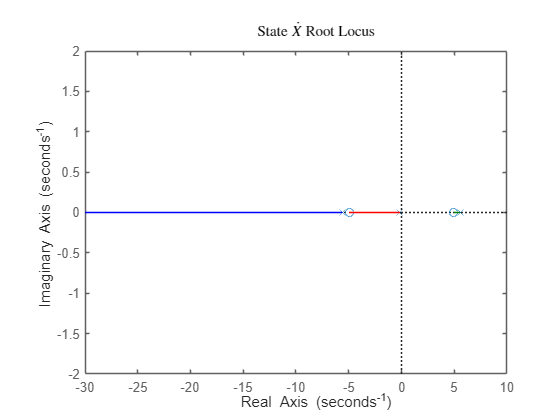

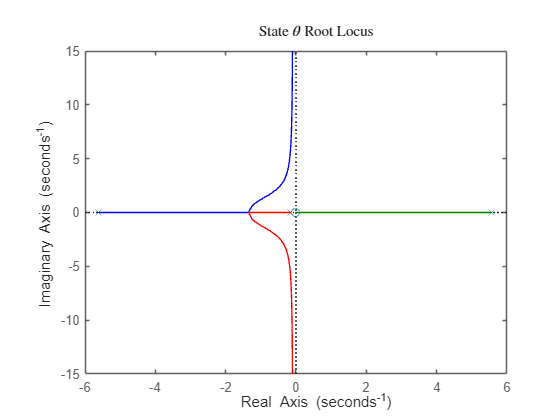

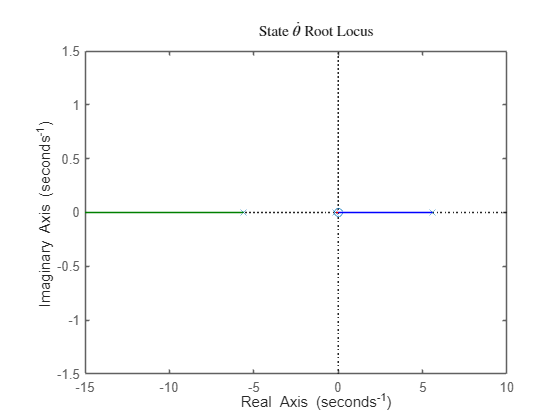

state = {'X','\dot{X}','\theta','\dot{\theta}'};

for i=1:1:size(sys_ss)
    figure();
    rlocus(sys_ss(i))
    title("State $"+ state(i) +"$ Root Locus",'Interpreter','latex');
end

The pole at 5.568 indicates that the system is unstable since the pole has positive real part. In other words, the pole is in the right half of the complex s-plane.

**2. Open-Loop Step Response**

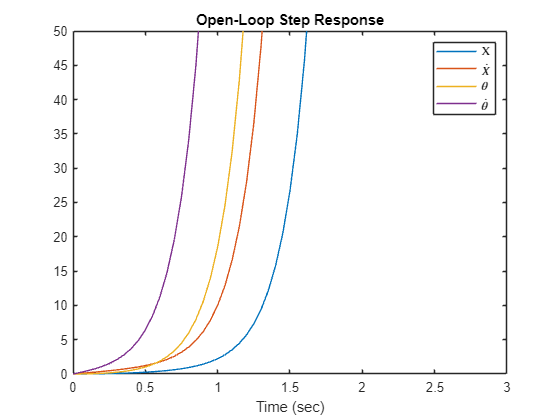

t = 0:0.05:10;
u = ones(size(t));
[y,t] = lsim(sys_ss,u,t);
figure();
plot(t,y)
title('Open-Loop Step Response')
axis([0 3 0 50])
legend({'X' '$\dot{X}$' '$\theta$' '$\dot{\theta}$'},Interpreter="latex");
xlabel("Time (sec)");

step_info = lsiminfo(y,t);
cart_info = step_info(1)

cart_info = struct with fields:
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 9.0368e+21
          MaxTime: 10


pend_info = step_info(2)

pend_info = struct with fields:
    TransientTime: 9.9959
     SettlingTime: 9.9959
              Min: 0
          MinTime: 0
              Max: 5.0316e+22
          MaxTime: 10


It is apparent from the analysis above that some sort of control will need to be designed to improve the response of the system.

**3. Controllability and Observability**

sys_co = ctrb(sys_ss)

sys_co =          0    1.8182   -0.3306   12.2213
    1.8182   -0.3306   12.2213   -4.4332
         0    4.5455   -0.8264  142.0304
    4.5455   -0.8264  142.0304  -31.3515


controllability = rank(sys_co)

controllability = 4

sys_ob = obsv(sys_ss)

sys_ob =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
         0    1.0000         0         0
         0   -0.1818    2.6755         0
         0         0         0    1.0000
         0   -0.4545   31.2136         0
         0   -0.1818    2.6755         0
         0    0.0331   -0.4864    2.6755


observability = rank(sys_ob)

observability = 4

The system is Controllable and Observable

## Linear Quadratic Regulation (LQR)

Q = [1 0 0 0; % Penalize X (cart position) error
     0 1 0 0; % Penalize X_dot (cart velocity) error
     0 0 1 0; % Penalize theta (pendulum angle) error
     0 0 0 1];% Penalize theta_dot (pendulum angular velocity) error

R = 1; % Penalize Force effort

x_init         = 1; % m
velocity_init  = -2; % m/s
theta_init     = 30;% degrees
theta_dot_init = 5; % degrees/sec

% Initial State 
X0 = [x_init;                   % X
      velocity_init;            % X_dot (Velocity of cart)
      deg2rad(theta_init);      % theta
      deg2rad(theta_dot_init)]; % theta_dot (Pendulum Angular Velocity)

[K_opt,P_opt,Poles_opt] = lqr(A,B,Q,R)

K_opt =    -1.0000   -2.0405   20.3838    3.9313


P_opt =     1.9405    1.3779   -3.9313   -0.7711
    1.3779    2.2031   -6.8577   -1.3301
   -3.9313   -6.8577   40.0897    7.2275
   -0.7711   -1.3301    7.2275    1.3969


Poles_opt =   -1.1020 + 0.4508i
  -1.1020 - 0.4508i
  -3.7503 + 0.0000i
  -8.3869 + 0.0000i


desired_lambda = [-1,-2,-3,-4]; 
max_iter = 7;

F = cell(max_iter+1,1);
P = cell(max_iter,1);
J = zeros([max_iter,1]);

F{1} = place(A,B,desired_lambda);
F_iter = [F{1}'];

for i=1:1:max_iter
    P{i} = lyap((A-B*F{i})',Q+F{i}'*R*F{i});
    F{i+1} = 1*R^(-1)*B'*P{i};

    J(i) = (1/2) * X0' * P{i} * X0;
    
    %for ploting F
    F_iter = [F_iter F{i+1}'];
end

P_iter = P{max_iter}

P_iter =     1.9405    1.3779   -3.9313   -0.7711
    1.3779    2.2031   -6.8577   -1.3301
   -3.9313   -6.8577   40.0897    7.2275
   -0.7711   -1.3301    7.2275    1.3969


K = F{max_iter+1}

K =    -1.0000   -2.0405   20.3838    3.9313


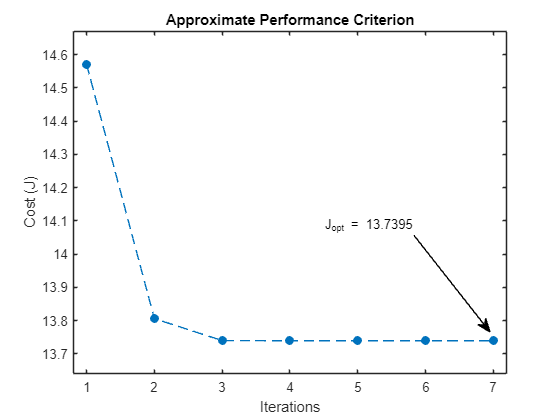

plot(1:max_iter,J,'.--','MarkerSize',20)

xlabel("Iterations");
ylabel("Cost (J)");

ylim([min(J)-0.1 max(J)+0.1]);
xlim([1-0.2 max_iter+0.2]);

title("Approximate Performance Criterion");

annotation("textarrow", [0.7393 0.875], [0.4395 0.2095], "String", "J_opt = "+min(J))

fmt = format;
format('longG');
J_table = array2table([(1:max_iter)' J],"VariableNames",{'Iterations','Cost (J)'})

J_table = 7×2 table
    Iterations        Cost (J)    
    __________    ________________

        1         14.5714602697248
        2         13.8059988941843
        3         13.7400265258361
        4         13.7394549763671
        5         13.7394549176283
        6         13.7394549176284
        7         13.7394549176283


J_opt = min(J)

J_opt =           13.7394549176283


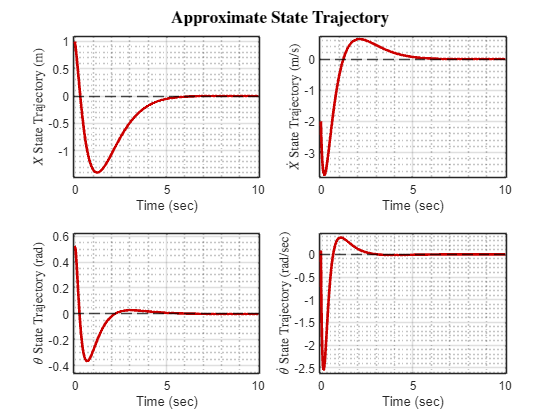

format(fmt);

X_t = @(t) expm( (A-(B*F{max_iter+1}))*t)*X0;
end_time = 10; %s
time = linspace(0,10,500);

X_iter = [];

for i=1:width(time)
    X_i= X_t(time(i));
    X_iter = [X_iter X_i];
    U(i) = -1*K*X_i;
end

state = {'X','\dot{X}','\theta','\dot{\theta}'};
state_unit = {'m','m/s','rad','rad/sec'};

figure();
for i=1:1:height(X_iter)
    subplot(2,2,i)
    plot(time,X_iter(i,:),'LineWidth',2,'Color','#CC0000');
    
    hold on;
    yline(0,'k--');
    hold off;

    xlabel("Time (sec)");
    y_txt = "$"+state(i)+"$ State Trajectory ("+state_unit(i)+")";
    ylabel(y_txt,'Interpreter','latex');
    
    grid;
    grid minor;

    ylim([min(X_iter(i,:))-0.1 max(X_iter(i,:)+0.1)]);
    xlim([min(time)-0.1 max(time)+0.1]);

    sgtitle("\bf Approximate State Trajectory",Interpreter="latex");
end

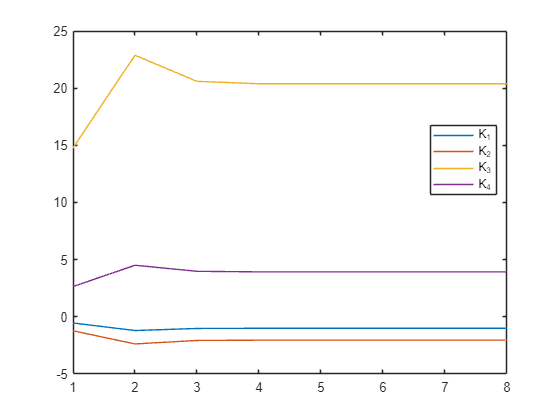

figure();
for i=1:1:height(F_iter)
    plot(1:max_iter+1,F_iter(i,:))
    hold on;
end
legend({'K_1','K_2','K_3','K_4'},Location="best");

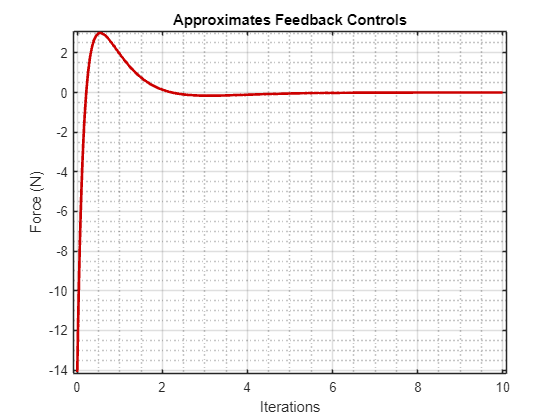


figure();
plot(time,U,'LineWidth',2,'Color','#CC0000');

xlabel("Iterations")
ylabel("Force (N)")

grid;
grid minor;

ylim([min(U)-0.1 max(U+0.1)]);
xlim([min(time)-0.1 max(time)+0.1]);

title("Approximates Feedback Controls")

We can see that the gain (K) we found iteratively is similar to the gain (K_opt) we found using provided MATLAB function LQR.

## System Response w/ LQR

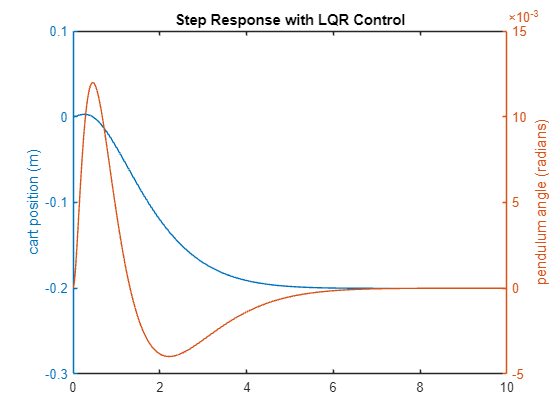

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [];

states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'r'};
outputs = {'X' '$\dot{X}$' '$\theta$' '$\dot{\theta}$'};

sys_cl = ss(Ac,Bc,Cc,Dc,'statename',states,'inputname',inputs,'outputname',outputs);

t = 0:0.01:10;
r =0.2*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,3),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
title('Step Response with LQR Control')

## Extension (LQR Tracking a Refrence)

LQR dirves all the states to zero. However what if we want want our cart to balance at a diffrent refrence point. we can denote this desired state as Xd and replace x by the error between the actual x and the desired x. By using this in LQR we minimize the error and can converge to desired state.

https://www.mtwallets.com/linear-quadratic-control-with-reference-input/ 

http://mae2.eng.uci.edu/~fjabbari//me270b/chap5.pdf


$$u=-K\;\left(X-X_d \right)$$


## Simulation Parameters

M = 0.5;
m = 0.2;
b = 0.1;
l = 0.3;
L = l*2;
I = 0.006;
g = 9.81;

p = I*(M+m)+M*m*l^2; %denominator for the A and B matrices

A = [0      1              0           0;
     0 -(I+m*l^2)*b/p  (m^2*g*l^2)/p   0;
     0      0              0           1;
     0 -(m*l*b)/p       m*g*l*(M+m)/p  0];

B = [     0;
     (I+m*l^2)/p;
          0;
        m*l/p];

C = eye(size(A));


D = [];

K = zeros([1 4]);

x_init         = 1; % m
velocity_init  = -2; % m/s
theta_init     = 30;% degrees
theta_dot_init = 5; % degrees/sec

% Initial State 
X0 = [x_init;                   % X
      velocity_init;            % X_dot (Velocity of cart)
      deg2rad(theta_init);      % theta
      deg2rad(theta_dot_init)]; % theta_dot (Pendulum Angular Velocity)

model = 'Inverted_Pendulum_LQR_Control';
Block = 'Inverted Pendulum';
StepSize = 0.01;
StopTime = 20;
RefBlock = 'Cart Positon Reference';
Ref_Pos = 0; % m
Disturbance_time = 11; %sec (@ 11 sec) 

## Simulink Simulation (No Input)

open_system(model);

set_param(model, ...
    "SaveFormat","Dataset", ...
    "LoadInitialState","off", ...
    'SolverType', 'Variable-step', ...
    'StopTime',num2str(StopTime));

% Set Cart's Refrence Position Block's Parameter
set_param([model '/' RefBlock], ...
    'Value',num2str(Ref_Pos));

% Set Manual Switch's Parameter
set_param([model '/' 'Input Switch'], ...
    'sw','1');

% Set Disturbance to 0;
set_param([model '/' 'Disturbance'], ...
    'ActiveScenario','NoDisturbance', ...
    'ActiveSignal','Constant_0');

initStates = Simulink.BlockDiagram.getInitialState(model);


for i=1:1:height(X0)
    initStates{i}.Values.Data = X0(i);
end

% Set Model's Parameter
set_param(model, ..., 
    "ReturnWorkspaceOutputs","on", ...
    "LoadInitialState","on", ...
    "InitialState","initStates", ...
    'SolverType', 'Fixed-step', ...
    'FixedStep',num2str(StepSize), ...
    'StopTime',num2str(StopTime));

NoInput.out = sim(model);

save_system(model);
close_system(model);

## Simulation Results (No Input)

NoInput.cart_pos = NoInput.out.sim_y(:,1);
NoInput.cart_vel = NoInput.out.sim_y(:,2);
NoInput.pend_ang = NoInput.out.sim_y(:,3);
NoInput.pend_vel = NoInput.out.sim_y(:,4);

NoInput.sim_u = zeros(size(NoInput.out.sim_t));

NoInput.sim_t = NoInput.out.sim_t;

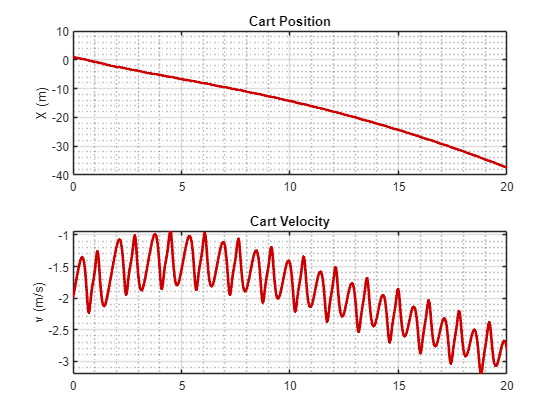

figure();
subplot(2,1,1);
plot(NoInput.sim_t,NoInput.cart_pos,'LineWidth',2,'Color','#CC0000');
ylabel("X (m)");
title("Cart Position");
grid on;
grid minor;

subplot(2,1,2);
plot(NoInput.sim_t,NoInput.cart_vel,'LineWidth',2,'Color','#CC0000');
ylabel("v (m/s)");
title("Cart Velocity");
grid on;
grid minor;

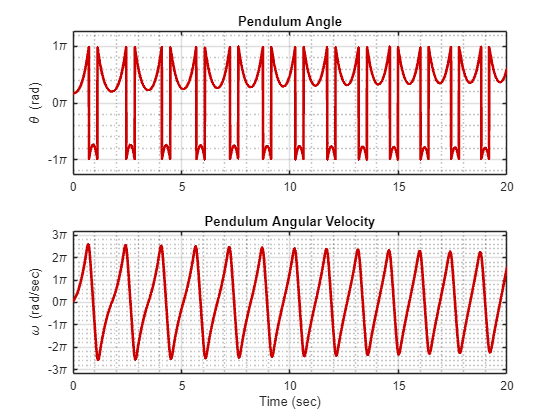

figure();
subplot(2,1,1);
plot(NoInput.sim_t,NoInput.pend_ang,'LineWidth',2,'Color','#CC0000');
ylabel("\theta (rad)");

pmin = min(NoInput.pend_ang);
pmax = max(NoInput.pend_ang);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angle");
grid on;
grid minor;


subplot(2,1,2);
plot(NoInput.sim_t,NoInput.pend_vel,'LineWidth',2,'Color','#CC0000');
xlabel("Time (sec)");
ylabel("\omega (rad/sec)");

pmin = min(NoInput.pend_vel);
pmax = max(NoInput.pend_vel);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angular Velocity");
grid on;
grid minor;

## Simulink Simulation (LQR)


$$Q=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;,R=1$$


Q = [1 0 0 0; % Penalize X (cart position) error
     0 1 0 0; % Penalize X_dot (cart velocity) error
     0 0 1 0; % Penalize theta (pendulum angle) error
     0 0 0 1];% Penalize theta_dot (pendulum angular velocity) error

R = 1; % Penalize Force effort

[K,P_opt,Poles_opt] = lqr(A,B,Q,R);

%Set Disturbance timing
dist = matfile("disturbance.mat","Writable",true);
ds = dist.Disturbance;
ts = ds.get('impulse');
ts.Time = [0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime];
ds = ds.setElement(1,ts);
dist.Distrubance = ds;

open_system(model);

set_param(model, ...
    "SaveFormat","Dataset", ...
    "LoadInitialState","off", ...
    'SolverType', 'Variable-step', ...
    'StopTime',num2str(StopTime));

% Set Cart's Refrence Position Block's Parameter
set_param([model '/' RefBlock], ...
    'Value',num2str(Ref_Pos));

% Set Manual Switch's Parameter
set_param([model '/' 'Input Switch'], ...
    'sw','0');

% Set Disturbance to 0;
set_param([model '/' 'Disturbance'], ...
    'ActiveScenario','Disturbance', ...
    'ActiveSignal','impulse');

initStates = Simulink.BlockDiagram.getInitialState(model);


for i=1:1:height(X0)
    initStates{i}.Values.Data = X0(i);
end

% Set Model's Parameter
set_param(model, ..., 
    "ReturnWorkspaceOutputs","on", ...
    "LoadInitialState","on", ...
    "InitialState","initStates", ...
    'SolverType', 'Fixed-step', ...
    'FixedStep',num2str(StepSize), ...
    'StopTime',num2str(StopTime));

out = sim(model);

save_system(model);
close_system(model);

## Simulation Results (LQR) [Q = *I , *R = 1] 

LQR_1_1.cart_pos = out.sim_y(:,1);
LQR_1_1.cart_vel = out.sim_y(:,2);
LQR_1_1.pend_ang = out.sim_y(:,3);
LQR_1_1.pend_vel = out.sim_y(:,4);

LQR_1_1.sim_u = out.sim_u;

LQR_1_1.sim_t = out.sim_t;

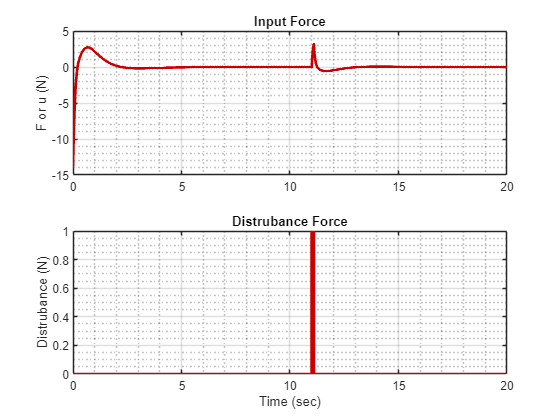

figure();
subplot(2,1,1);
plot(LQR_1_1.sim_t,LQR_1_1.sim_u,'LineWidth',2,'Color','#CC0000');
ylabel("F or u (N)");
grid on;
grid minor;
title("Input Force");

subplot(2,1,2);
plot([0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime],[0 0 1 1 0 0],'LineWidth',2,'Color','#CC0000');
ylabel("Distrubance (N)");
xlabel("Time (sec)");
grid on;
grid minor;
title("Distrubance Force");

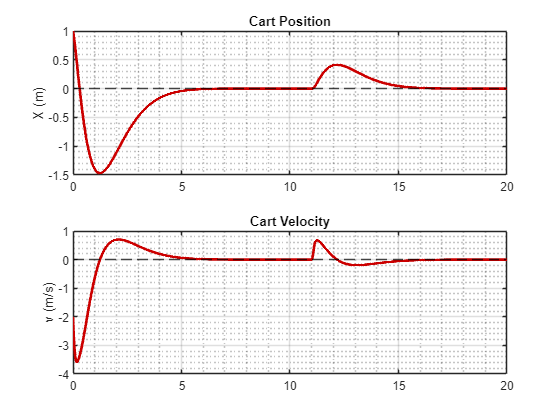

figure();
subplot(2,1,1);
plot(LQR_1_1.sim_t,LQR_1_1.cart_pos,'LineWidth',2,'Color','#CC0000');

ylabel("X (m)");
title("Cart Position");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

subplot(2,1,2);
plot(LQR_1_1.sim_t,LQR_1_1.cart_vel,'LineWidth',2,'Color','#CC0000');

ylabel("v (m/s)");
title("Cart Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

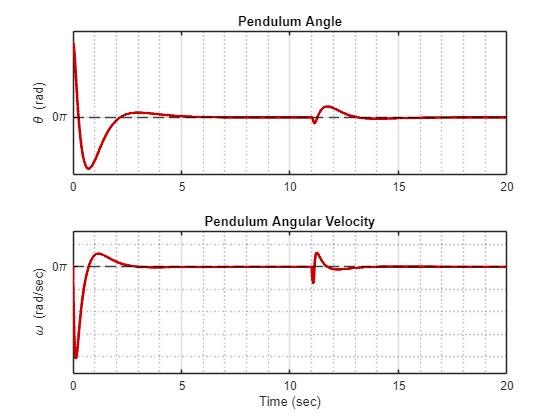

figure();
subplot(2,1,1);
plot(LQR_1_1.sim_t,LQR_1_1.pend_ang,'LineWidth',2,'Color','#CC0000');
ylabel("\theta (rad)");

pmin = min(LQR_1_1.pend_ang);
pmax = max(LQR_1_1.pend_ang);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angle");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;


subplot(2,1,2);
plot(LQR_1_1.sim_t,LQR_1_1.pend_vel,'LineWidth',2,'Color','#CC0000');
xlabel("Time (sec)");
ylabel("\omega (rad/sec)");

pmin = min(LQR_1_1.pend_vel);
pmax = max(LQR_1_1.pend_vel);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angular Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

## Simulink Simulation (LQR)


$$Q=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;,R=10$$


Q = [1 0 0 0; % Penalize X (cart position) error
     0 1 0 0; % Penalize X_dot (cart velocity) error
     0 0 1 0; % Penalize theta (pendulum angle) error
     0 0 0 1];% Penalize theta_dot (pendulum angular velocity) error

R = 10; % Penalize Force effort

[K,P_opt,Poles_opt] = lqr(A,B,Q,R);

%Set Disturbance timing
dist = matfile("disturbance.mat","Writable",true);
ds = dist.Disturbance;
ts = ds.get('impulse');
ts.Time = [0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime];
ds = ds.setElement(1,ts);
dist.Distrubance = ds;

open_system(model);

set_param(model, ...
    "SaveFormat","Dataset", ...
    "LoadInitialState","off", ...
    'SolverType', 'Variable-step', ...
    'StopTime',num2str(StopTime));

% Set Cart's Refrence Position Block's Parameter
set_param([model '/' RefBlock], ...
    'Value',num2str(Ref_Pos));

% Set Manual Switch's Parameter
set_param([model '/' 'Input Switch'], ...
    'sw','0');

% Set Disturbance to 0;
set_param([model '/' 'Disturbance'], ...
    'ActiveScenario','Disturbance', ...
    'ActiveSignal','impulse');

initStates = Simulink.BlockDiagram.getInitialState(model);


for i=1:1:height(X0)
    initStates{i}.Values.Data = X0(i);
end

% Set Model's Parameter
set_param(model, ..., 
    "ReturnWorkspaceOutputs","on", ...
    "LoadInitialState","on", ...
    "InitialState","initStates", ...
    'SolverType', 'Fixed-step', ...
    'FixedStep',num2str(StepSize), ...
    'StopTime',num2str(StopTime));

LQR_1_10.out = sim(model);

save_system(model);
close_system(model);

## Simulation Results (LQR) [Q = *I , R = 10*]

LQR_1_10.cart_pos = LQR_1_10.out.sim_y(:,1);
LQR_1_10.cart_vel = LQR_1_10.out.sim_y(:,2);
LQR_1_10.pend_ang = LQR_1_10.out.sim_y(:,3);
LQR_1_10.pend_vel = LQR_1_10.out.sim_y(:,4);

LQR_1_10.sim_u = LQR_1_10.out.sim_u;

LQR_1_10.sim_t = LQR_1_10.out.sim_t;

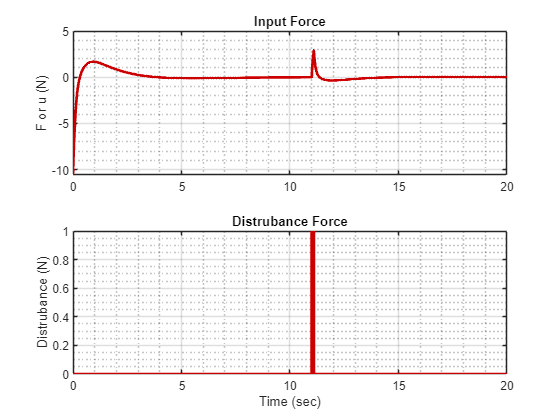

figure();
subplot(2,1,1);
plot(LQR_1_10.sim_t,LQR_1_10.sim_u,'LineWidth',2,'Color','#CC0000');
ylabel("F or u (N)");
grid on;
grid minor;
title("Input Force");

subplot(2,1,2);
plot([0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime],[0 0 1 1 0 0],'LineWidth',2,'Color','#CC0000');
ylabel("Distrubance (N)");
xlabel("Time (sec)");
grid on;
grid minor;
title("Distrubance Force");

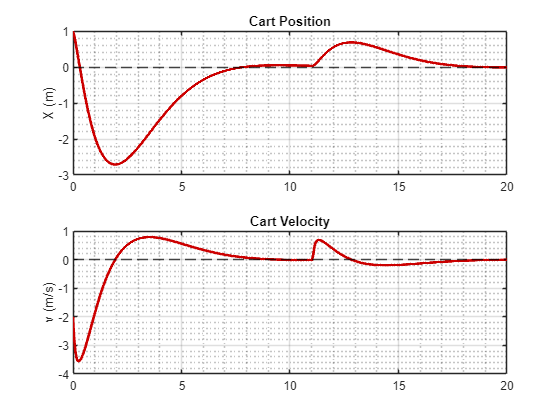

figure();
subplot(2,1,1);
plot(LQR_1_10.sim_t,LQR_1_10.cart_pos,'LineWidth',2,'Color','#CC0000');
ylabel("X (m)");
title("Cart Position");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

subplot(2,1,2);
plot(LQR_1_10.sim_t,LQR_1_10.cart_vel,'LineWidth',2,'Color','#CC0000');
ylabel("v (m/s)");
title("Cart Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

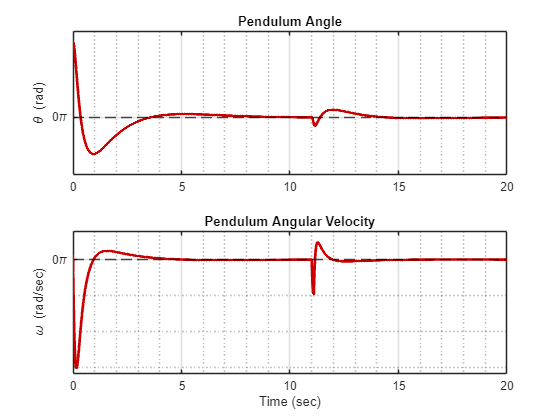

figure();
subplot(2,1,1);
plot(LQR_1_10.sim_t,LQR_1_10.pend_ang,'LineWidth',2,'Color','#CC0000');
ylabel("\theta (rad)");

pmin = min(LQR_1_10.pend_ang);
pmax = max(LQR_1_10.pend_ang);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angle");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

subplot(2,1,2);
plot(LQR_1_10.sim_t,LQR_1_10.pend_vel,'LineWidth',2,'Color','#CC0000');
xlabel("Time (sec)");
ylabel("\omega (rad/sec)");

pmin = min(LQR_1_10.pend_vel);
pmax = max(LQR_1_10.pend_vel);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angular Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

## Simulink Simulation (LQR)


$$Q=\left\lbrack \begin{array}{cccc}
10 & 0 & 0 & 0\\
0 & 10 & 0 & 0\\
0 & 0 & 10 & 0\\
0 & 0 & 0 & 10
\end{array}\right\rbrack \;,R=1$$


Q = [10 0 0 0; % Penalize X (cart position) error
     0 10 0 0; % Penalize X_dot (cart velocity) error
     0 0 10 0; % Penalize theta (pendulum angle) error
     0 0 0 10];% Penalize theta_dot (pendulum angular velocity) error

R = 1; % Penalize Force effort

[K,P_opt,Poles_opt] = lqr(A,B,Q,R);
%Set Disturbance timing
dist = matfile("disturbance.mat","Writable",true);
ds = dist.Disturbance;
ts = ds.get('impulse');
ts.Time = [0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime];
ds = ds.setElement(1,ts);
dist.Distrubance = ds;

open_system(model);

set_param(model, ...
    "SaveFormat","Dataset", ...
    "LoadInitialState","off", ...
    'SolverType', 'Variable-step', ...
    'StopTime',num2str(StopTime));

% Set Cart's Refrence Position Block's Parameter
set_param([model '/' RefBlock], ...
    'Value',num2str(Ref_Pos));

% Set Manual Switch's Parameter
set_param([model '/' 'Input Switch'], ...
    'sw','0');

% Set Disturbance to 0;
set_param([model '/' 'Disturbance'], ...
    'ActiveScenario','Disturbance', ...
    'ActiveSignal','impulse');

initStates = Simulink.BlockDiagram.getInitialState(model);


for i=1:1:height(X0)
    initStates{i}.Values.Data = X0(i);
end

% Set Model's Parameter
set_param(model, ..., 
    "ReturnWorkspaceOutputs","on", ...
    "LoadInitialState","on", ...
    "InitialState","initStates", ...
    'SolverType', 'Fixed-step', ...
    'FixedStep',num2str(StepSize), ...
    'StopTime',num2str(StopTime));

LQR_10_1.out = sim(model);

save_system(model);
close_system(model);

## Simulation Results (LQR) [Q = 10 , R  = 1]

LQR_10_1.cart_pos = LQR_10_1.out.sim_y(:,1);
LQR_10_1.cart_vel = LQR_10_1.out.sim_y(:,2);
LQR_10_1.pend_ang = LQR_10_1.out.sim_y(:,3);
LQR_10_1.pend_vel = LQR_10_1.out.sim_y(:,4);

LQR_10_1.sim_u = LQR_10_1.out.sim_u;

LQR_10_1.sim_t = LQR_10_1.out.sim_t;

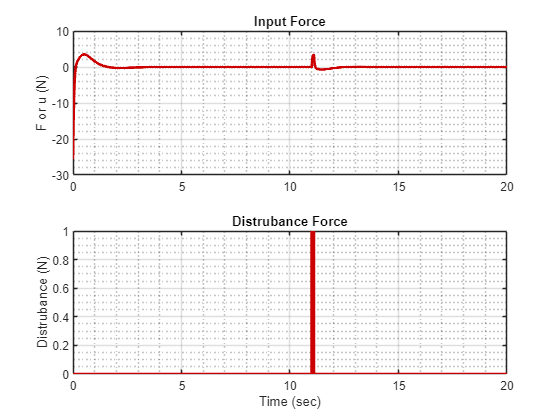

figure();
subplot(2,1,1);
plot(LQR_10_1.sim_t,LQR_10_1.sim_u,'LineWidth',2,'Color','#CC0000');
ylabel("F or u (N)");
grid on;
grid minor;
title("Input Force");

subplot(2,1,2);
plot([0 Disturbance_time Disturbance_time Disturbance_time+0.1 Disturbance_time+0.1 StopTime],[0 0 1 1 0 0],'LineWidth',2,'Color','#CC0000');
ylabel("Distrubance (N)");
xlabel("Time (sec)");
grid on;
grid minor;
title("Distrubance Force");

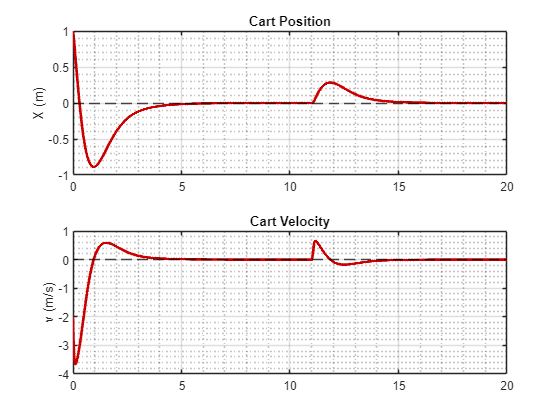

figure();
subplot(2,1,1);
plot(LQR_10_1.sim_t,LQR_10_1.cart_pos,'LineWidth',2,'Color','#CC0000');
ylabel("X (m)");
title("Cart Position");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

subplot(2,1,2);
plot(LQR_10_1.sim_t,LQR_10_1.cart_vel,'LineWidth',2,'Color','#CC0000');
ylabel("v (m/s)");
title("Cart Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

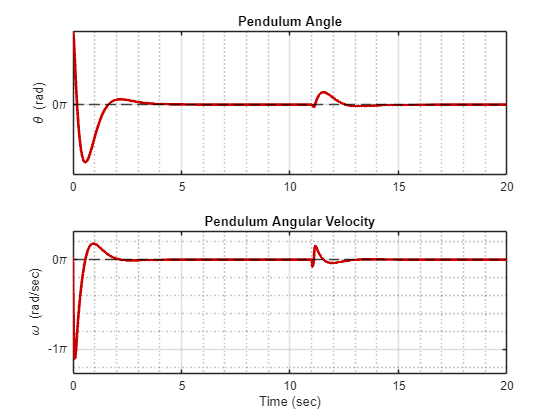

figure();
subplot(2,1,1);
plot(LQR_10_1.sim_t,LQR_10_1.pend_ang,'LineWidth',2,'Color','#CC0000');
ylabel("\theta (rad)");

pmin = min(LQR_10_1.pend_ang);
pmax = max(LQR_10_1.pend_ang);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angle");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;


subplot(2,1,2);
plot(LQR_10_1.sim_t,LQR_10_1.pend_vel,'LineWidth',2,'Color','#CC0000');
xlabel("Time (sec)");
ylabel("\omega (rad/sec)");

pmin = min(LQR_10_1.pend_vel);
pmax = max(LQR_10_1.pend_vel);
pimin = floor(pmin/pi);
pimax = ceil(pmax/pi);
yticks((pimin:pimax) * pi);
yticklabels( string(pimin:pimax) + "\pi" );

title("Pendulum Angular Velocity");

hold on;
yline(0,'k--');
hold off;

grid on;
grid minor;

## Reset Simulink Parameters

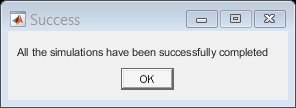

Q = [1 0 0 0; % Penalize X (cart position) error
     0 1 0 0; % Penalize X_dot (cart velocity) error
     0 0 1 0; % Penalize theta (pendulum angle) error
     0 0 0 1];% Penalize theta_dot (pendulum angular velocity) error

R = 1; % Penalize Force effort

[K,P_opt,Poles_opt] = lqr(A,B,Q,R);

load_system(model);

set_param(model, ...
    "LoadInitialState","off", ...
    'FixedStep',num2str(StepSize), ...
    'SolverType', 'Fixed-step', ...
    "ReturnWorkspaceOutputs","on", ...
    'StopTime','inf');

% Set Cart's Refrence Position Block's Parameter
set_param([model '/' RefBlock], ...
    'Value',num2str(0));

% Set Manual Switch's Parameter
set_param([model '/' 'Input Switch'], ...
    'sw','0');

% Set Disturbance to 0;
set_param([model '/' 'Disturbance'], ...
    'ActiveScenario','Disturbance', ...
    'ActiveSignal','impulse');

save_system(model);

msgbox("All the simulations have been successfully completed","Success");

open_system(model);